读取图片,存储在img_list和cell_list中。如需要运行则先修改第一行的path为绝对路径。

path = 'C:\Users\asus\Desktop\模式识别大作业\模式识别\final\tool\rename';
files = dir(path);
files = files(3:42);

img_list = cell(1,40);
label_list = cell(1,40);

label_num = 40;
for i=1:label_num
    imgs_path = [path,'\',files(i).name];
    % imgs = dir(fullfile(imgs_path,'*.jpg'));
    img_list{i} = imread(imgs_path);
    label_list{i} = imgs_path(length(imgs_path) - 5);
end 

灰度化，二值化，尺寸缩放到64X64

contour = cell(1,64);
for i=1:length(img_list)
    I2 = rgb2gray(img_list{i});
    T = graythresh(I2);
    I2 = imbinarize(I2,T);
    img_list{i} = imresize(I2, [64,64]);
end

使用圆形面积比重并归一化，此处运行matlab会警告

area_circle = zeros(1,40);
for i=1:40
    [centers,radii] = imfindcircles(img_list{i},[1,64]);
    area_circle(i) = sum(pi.* radii.^2)./(64^2);
end

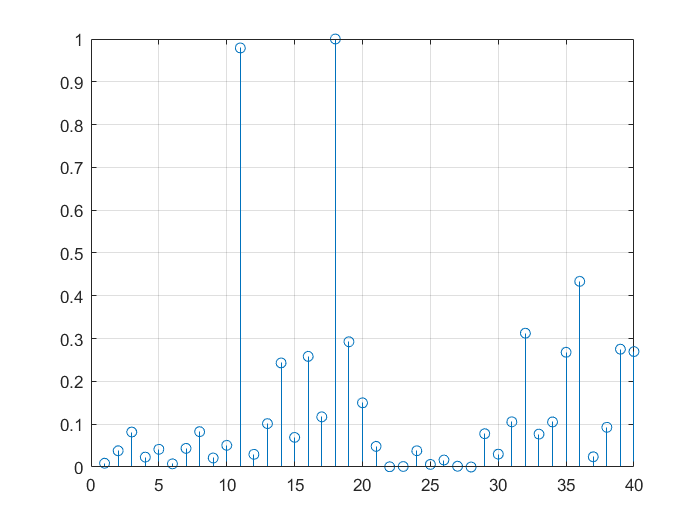

area_circle = (area_circle-min(area_circle))/(max(area_circle)-min(area_circle));
figure(1)
stem(1:40, area_circle);
grid on

计算二值图像中的1的个数除以像素点总数，同样进行归一化

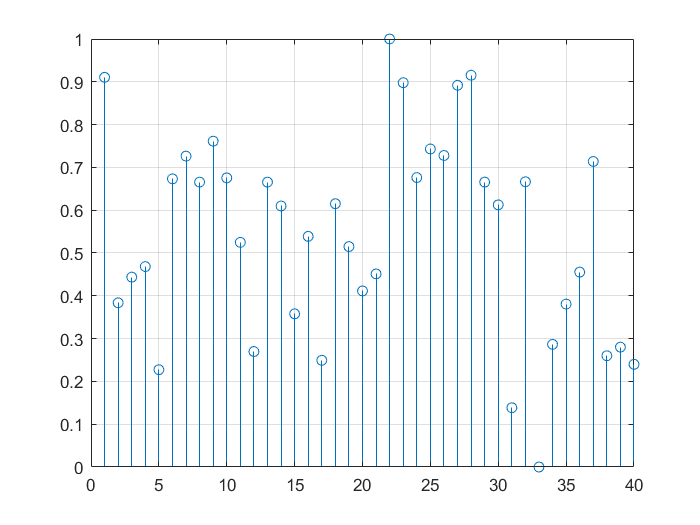

area = zeros(1,40);
for i=1:40
    area(i) = sum(sum(img_list{i}));
end
area = (area-min(area))/(max(area)-min(area));
figure(2)
stem(1:40, area);
grid on

绘制散点图f1 vs f2

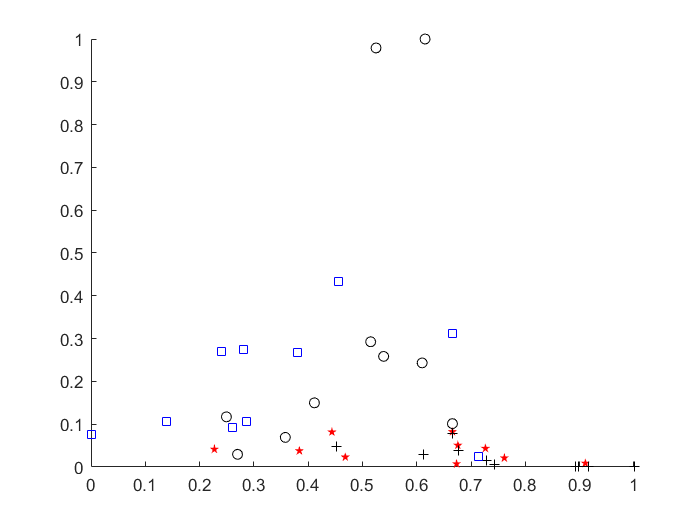

figure(3)
scatter(area(1:10), area_circle(1:10), 'r','p','filled');
hold on
scatter(area(11:20), area_circle(11:20), 'black');
hold on
scatter(area(21:30), area_circle(21:30), 30,'k','+');
hold on
scatter(area(31:40), area_circle(31:40), 45,'b','s');

求四连域f3

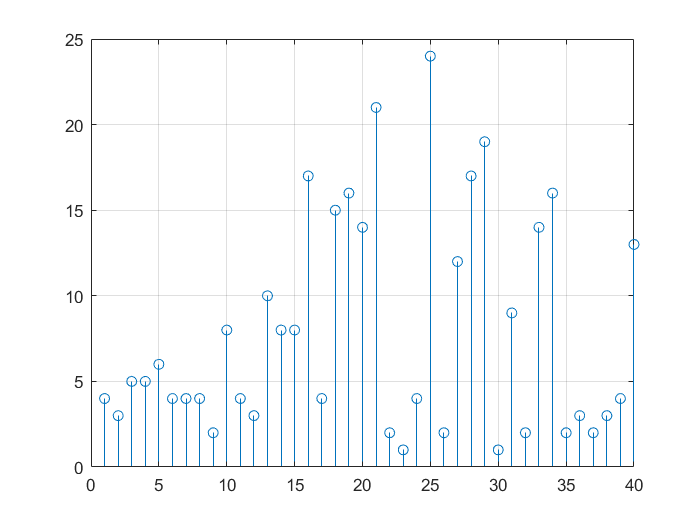

liantong = zeros(1,40);
for i=1:40
    [L, num] = bwlabel(img_list{i},4);
    liantong(i) = num;
end
figure(4)
stem(1:40, liantong);
grid on

合并三个特征到一个矩阵中，方便调用APP进行分类

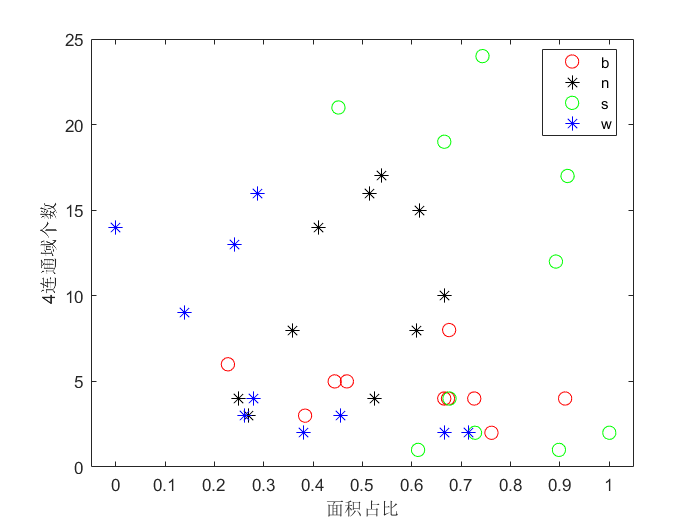

label=ones(1, 40);
for i=1:40
    if(label_list{i} == 'b')
        label(i) = 0;
    end
    if(label_list{i} == 'n')
        label(i) = 1;
    end
    if(label_list{i} == 's')
        label(i) = 2;
    end
    if(label_list{i} == 'w')
        label(i) = 3;
    end
end
data = [area', area_circle', liantong' ,label'];
figure(5)
gscatter(data(:,1),data(:,3),label_list','rkgb','o*',8,'on','面积占比','4连通域个数')

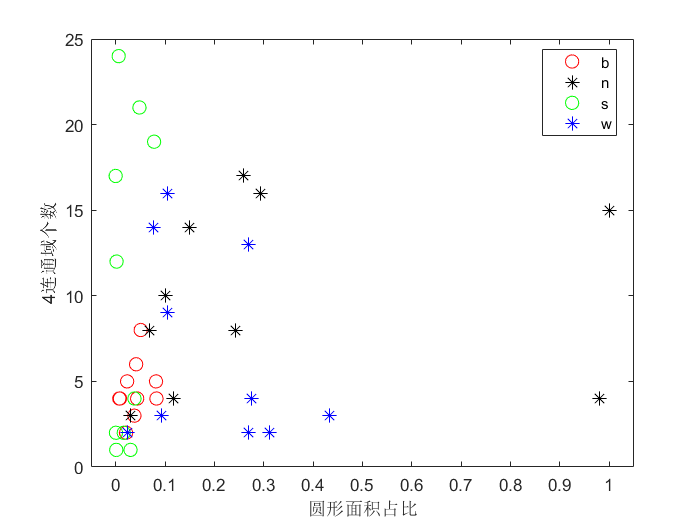

figure(6)
gscatter(data(:,2),data(:,3),label_list','rkgb','o*',8,'on','圆形面积占比','4连通域个数')

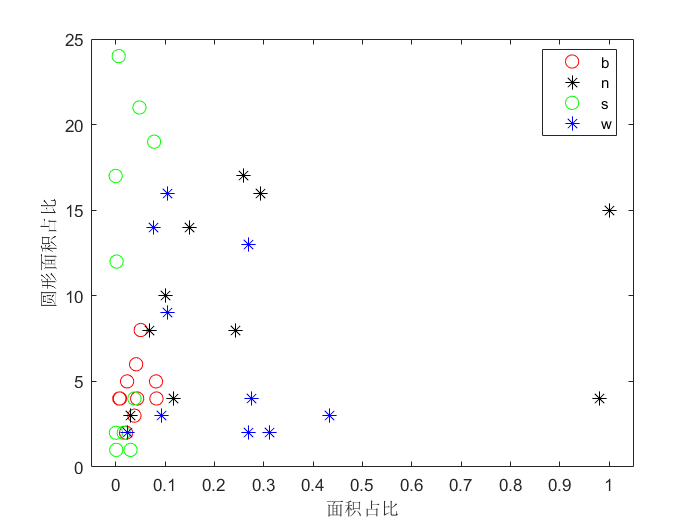

figure(7)
gscatter(data(:,2),data(:,3),label_list','rkgb','o*',8,'on','面积占比','圆形面积占比')

求欧式距离

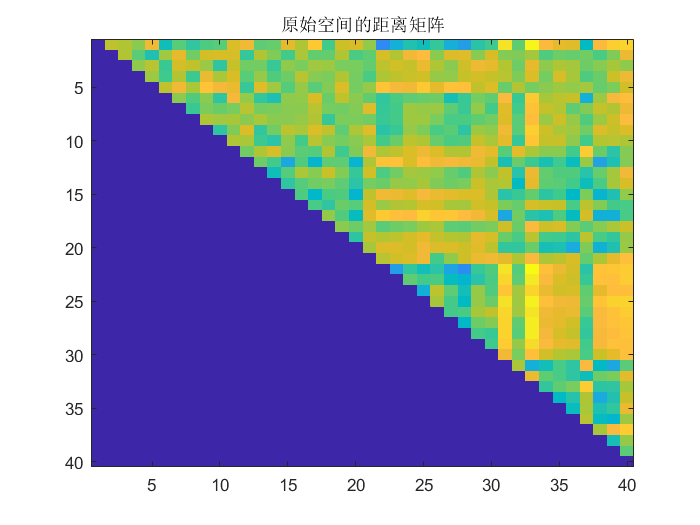

distance = zeros(40,40);
for i=1:40
    for j=i+1:40
        distance(i,j) = sqrt(sum(sum((img_list{i}-img_list{j}).^2)));
    end
end

feature_distance = zeros(40,40);
for i=1:40
    for j=i+1:40
        feature_distance(i,j) = sqrt((data(i,1)-data(j,1))^2+(data(i,2)-data(j,2))^2+(data(i,3)-data(j,3))^2);
    end
end
figure(8)
imagesc(distance);
title('原始空间的距离矩阵')

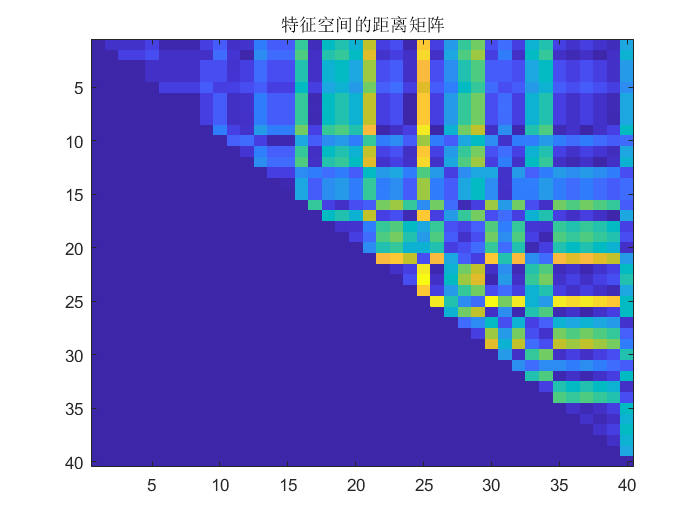

figure(9)
imagesc(feature_distance)
title('特征空间的距离矩阵')

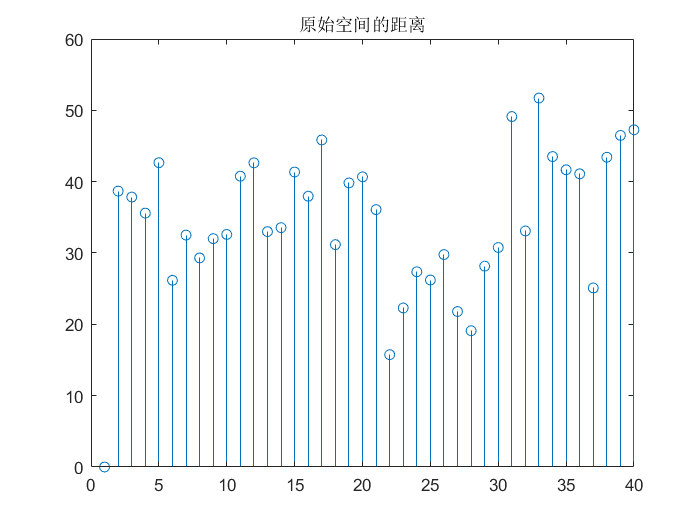


figure(10)
stem(1:40, distance(1,:));
title('原始空间的距离');

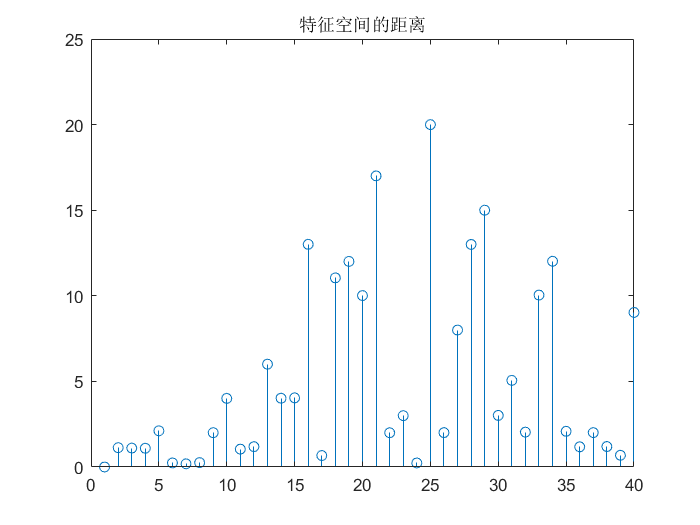

figure(11)
stem(1:40, feature_distance(1,:));
title('特征空间的距离');